# Exploration of 2013 Storm Events

## Introduction

The data file contains a list of weather events that occurred in the United States in 2013. The events have been categorized by type and the state in which they occurred. There is also information about 

- damage costs

- number of resulting injuries

- location of some of the events

StormEvents = importStormEvents("StormEvents_2014.csv");

% Reorder months
month = ["January","February","March","April","May","June","July","August","September","October","November","December"];
StormEvents.Month = reordercats(StormEvents.Month,month);
head(StormEvents)

ans = 8×13 table
        State         Month      Event_Type       Begin_Date_Time         End_Date_Time       Injuries_Direct    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                Event_Narrative                                                                                                                                            
    _____________    ________    ___________    ___________________    ___________________    _______________    _____________    _________

## Visualize raw data

Create a heat map to look at the frequency of each event type by month.

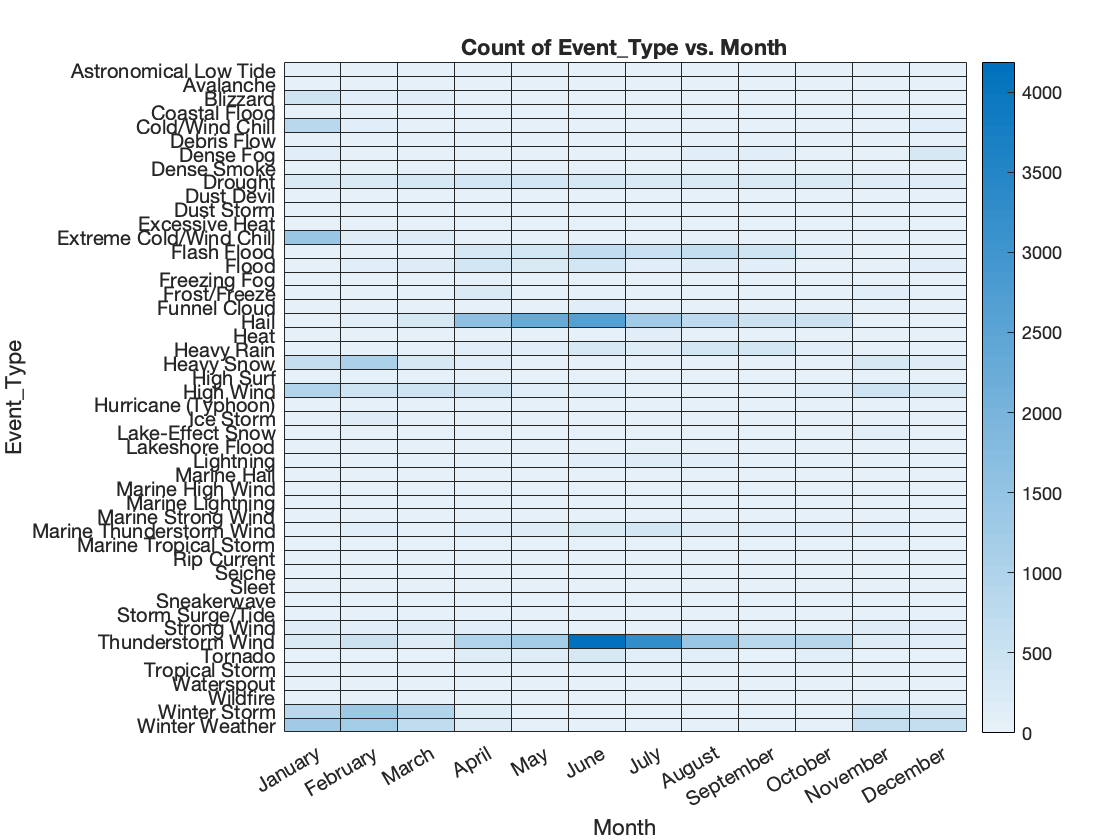

% Count of events by type and month
heatmap(StormEvents,"Month","Event_Type");

## Explore Hail and Thunderstorm Wind

There is a higher occurrence of Hail and Thunderstorm Wind in the summer months. Further analysis will see if there is a relationship between these two events.

% Creating a new plot - geodensity
Hind = StormEvents.Event_Type=="Hail";
geodensityplot(StormEvents.Begin_Lat(Hind),StormEvents.Begin_Lon(Hind))
% Just show continental US
geolimits([17.0 55.2],[-128.0 -65.6])

Add Thunderstorm Wind to see if they are related.

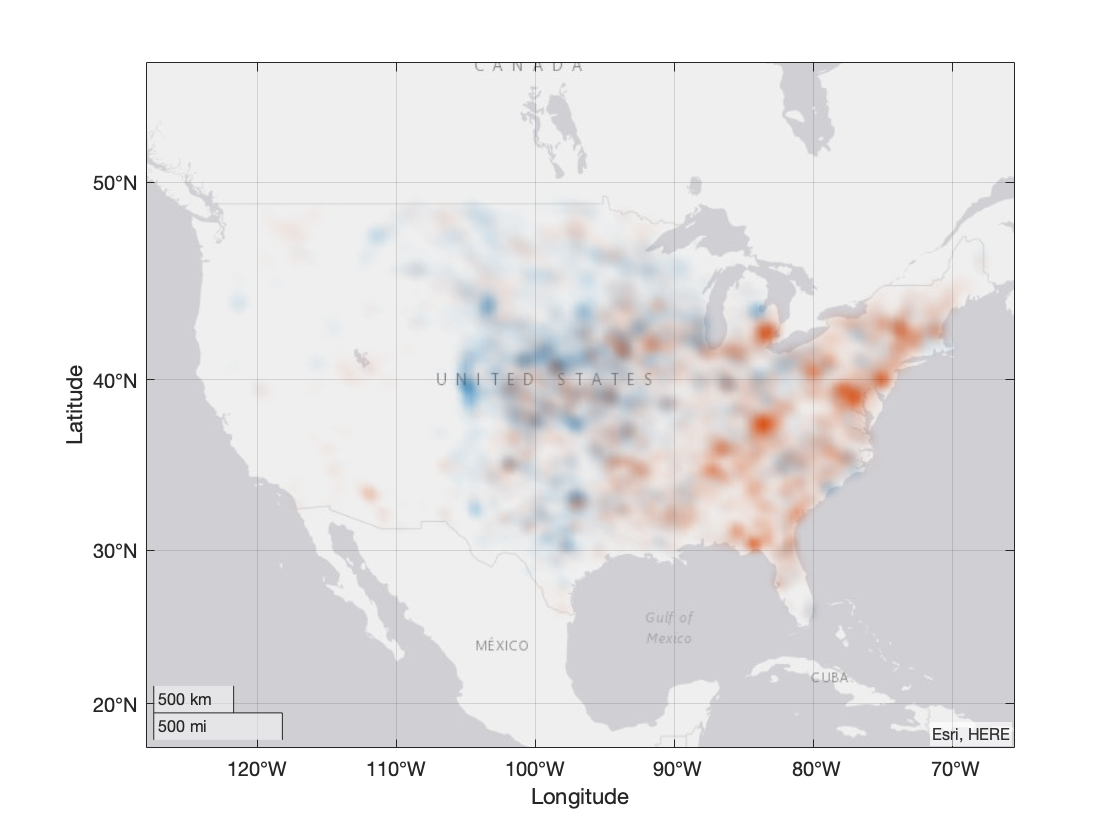

hold on
TWind = StormEvents.Event_Type=="Thunderstorm Wind";
geodensityplot(StormEvents.Begin_Lat(TWind),StormEvents.Begin_Lon(TWind))
hold off

When looking across all states, there does not appear to be a relationship between hail and thunderstorm wind. Hail appears to be concentrated in the central United States while thunderstorm wind is concentrated in the eastern United States. However, there still may be some storms where both events occurred. Looking at events in a single state may show this.

## Texas

The geodenisty plot shows some potential overlapping hail and thunderstorm wind events in Texas.

% Creating a new plot - geodensity
Hind = StormEvents.Event_Type=="Hail" & StormEvents.State=="TEXAS";
geodensityplot(StormEvents.Begin_Lat(Hind),StormEvents.Begin_Lon(Hind))

Add Thunderstorm Wind to see if they are related.

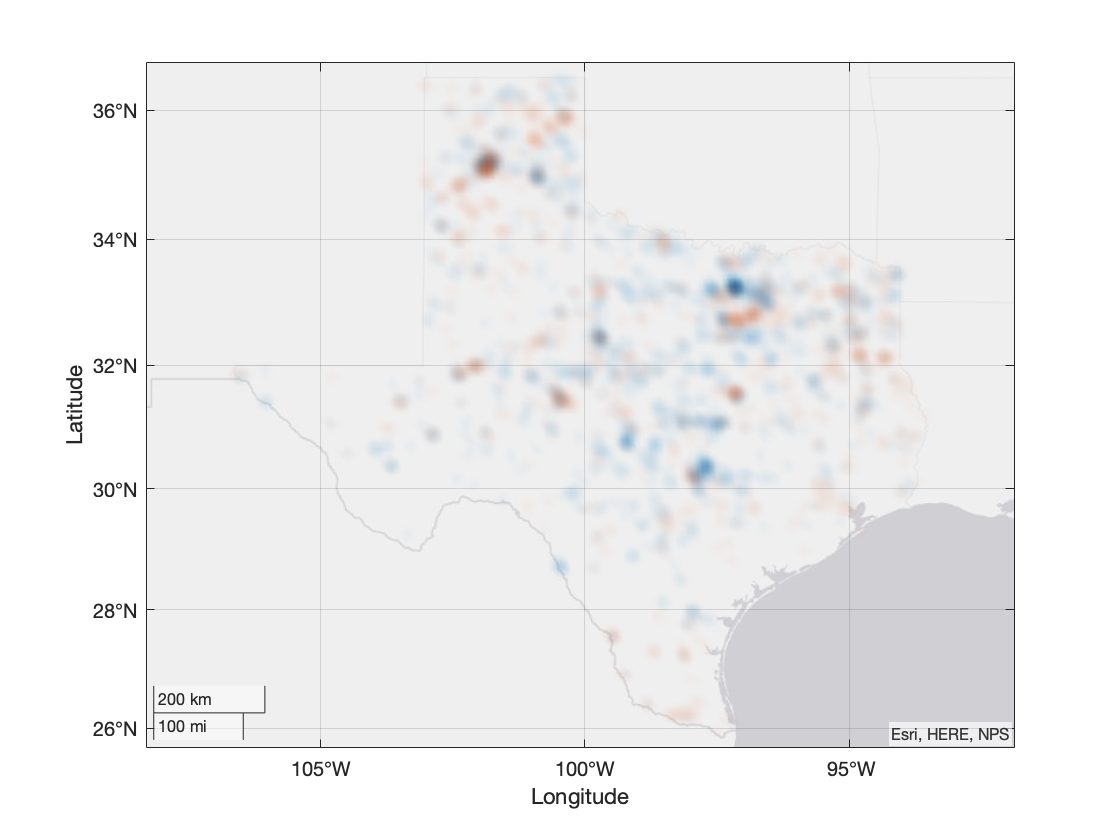

hold on
TWind = StormEvents.Event_Type=="Thunderstorm Wind" & StormEvents.State=="TEXAS";
geodensityplot(StormEvents.Begin_Lat(TWind),StormEvents.Begin_Lon(TWind))
hold off

While it appears most of the events are unrelated, some of the events do overlap. The large concentration at the top is near Amarillo, Texas. Looking at that cluster of events may show a relationship.

## Amarillo, TX

Both hail and thunderstorm wind events contain latitude and longitude values. Use this to select events that occurred within a specified distance of Amarillo. The coordinates for Amarillo, TX were obtained online.

amarilloTX = [35.221996 -101.831299]; % [latitude longitude]

Distance from Amarillo can be computed using the [Haversine formula](https://www.movable-type.co.uk/scripts/latlong.html):


$$a = \sin^2(\frac{lat_1-lat_2}{2}) + \cos(lat_1)\cdot \cos(lat_2)\cdot \sin^2(\frac{lon_1-lon_2}{2})$$



$$c = 2\cdot \text{atan2}(\sqrt{a}, \sqrt{(1-a)})$$



$$d = R\cdot c$$


dLat = StormEvents.Begin_Lat - amarilloTX(1);
dLon = StormEvents.Begin_Lon - amarilloTX(2);

% Haversine formula
R = 6371; % earth's radius, kilometers
a = sind(dLat/2).^2 + cosd(StormEvents.Begin_Lat).*cosd(StormEvents.End_Lat).*sind(dLon/2).^2;
c = 2*atan2(sqrt(a),sqrt(1-a));

% Add distance to data table
StormEvents.Dist_m = R*c; % kilometers

% Select all hail and thunderstorm wind events that occurred within 8 km (~5 miles) of Amarillo, TX.
dist = 8; % kilometers
events = StormEvents((StormEvents.Event_Type=="Hail" | ...
    StormEvents.Event_Type=="Thunderstorm Wind") & ...
    StormEvents.Dist_m < dist,:)

events = 19×14 table
    State      Month         Event_Type          Begin_Date_Time         End_Date_Time       Injuries_Direct    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                 Event_Narrative                                                                                                                                                                                                                                                  Dist_m
    _____    _________

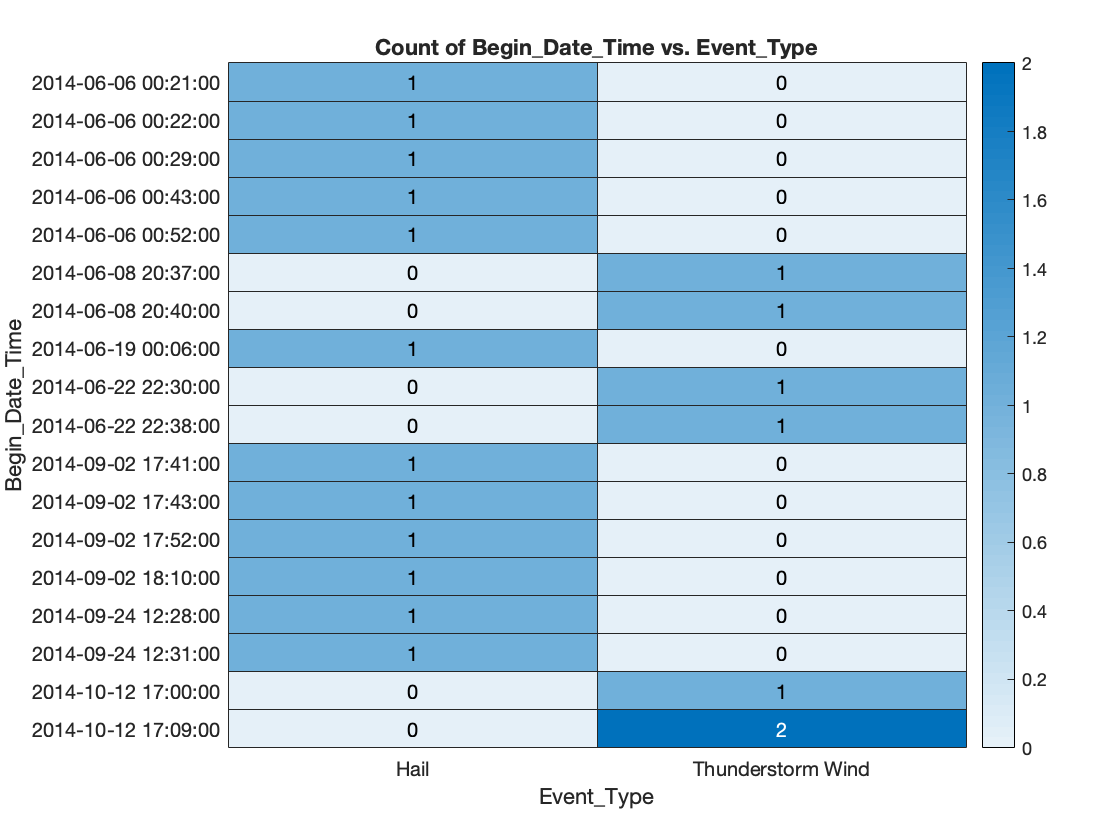


events.Event_Type = removecats(events.Event_Type); % remove empty categories
heatmap(events,"Event_Type","Begin_Date_Time");

So far, the analysis has only used location to identify a potential relationship between hail and thunderstorm wind events. However, the events must also occur around the same time to be related. Since the number of events has been reduced by the filtering, the simplest way of visualizing location and date is with a heatmap of event type and date.

## Conclusion

The main contributing factor in the formation of hail is wind. It would therefore be reasonable to expect some relationship between hail and thunderstorm wind events. This preliminary investigation into these two events would suggest that, at least in this data set, there is not a strong relationship.

A comparison of the events by concentration shows most hail events occur in the central United States while most thunderstorm wind events occur in the east. There are exceptions, but it is necessary to look at individual storms to identify potential relationships.

One such storm was found to hit the Amarillo, Texas area on May 28, 2013. Eight thunderstorm wind events were recorded between 16:16 and 17:11. Then starting at 22:35, nine hail events were recorded, with the last one starting at 23:14.

Additional work is necessary to determine if the thunderstorm wind events did in fact contribute to the hail events.